# Electrode localization using FreeSurfer + iElectrodes

Written by Qian Chu (Max Planck - University of Toronto Centre)

Contact: qian.chu@{mail.utoronto.ca, ae.mpg.de, nyu.edu}

Version: 20230721

## Checklist

Make sure that you have:

- Acquired the pre-op T1-weighted MRI and post-op CT images (and T2-weighted MRI if possible) and converted them from DICOM (.dcm) to NIFTI (.nii) files. This can done using softwares like MRIcroGL ([https://www.nitrc.org/projects/mricrogl](https://www.nitrc.org/projects/mricrogl)) or using the mri_convert command in FreeSurfer ([https://surfer.nmr.mgh.harvard.edu/fswiki/mri_convert](https://surfer.nmr.mgh.harvard.edu/fswiki/mri_convert))

- FreeSurfer installed on this computer (this script has been validated with FreeSurfer 7.3.2). FreeSurfer can be installed on Linux or MacOS. For Windows, you will need WSL (Windows Subsystem for Linux). Download instructions: [https://surfer.nmr.mgh.harvard.edu/fswiki/rel7downloads.](https://surfer.nmr.mgh.harvard.edu/fswiki/rel7downloads.) It is also recommended you set up automatic sourcing so that FreeSurfer commands are immediately available after opening a terminal. For instructions see [https://surfer.nmr.mgh.harvard.edu/fswiki/SetupConfiguration_Linux](https://surfer.nmr.mgh.harvard.edu/fswiki/SetupConfiguration_Linux)

- Downloaded iElectrodes from [https://sourceforge.net/projects/ielectrodes/files/latest/download](https://sourceforge.net/projects/ielectrodes/files/latest/download) and put the unzipped package in this elec_loc folder.

## Run sections below one by one

## Setup

In *elec_loc/config.json*, specify paths:

- To FreeSurfer home directory <"dir_fs": "$FREESURFER_HOME">

- To subject directory <"dir_fs_subjects": "$SUBJECTS_DIR">

$FREESURFER_HOME and $SUBJECTS_DIR can be found in the command line outputs when you source FreeSurfer using SetUpFreeSurfer.sh

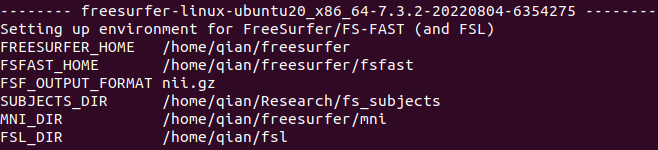

clearvars, clc, close all

elec_loc_path       = matlab.desktop.editor.getActiveFilename;
elec_loc_path_parts = split(elec_loc_path, {'/', '\'});
elec_loc_dir        = strjoin(elec_loc_path_parts(1:end-1), '/');

% Set up path
cd(elec_loc_dir)

iel_info = dir('iElectrodes*');
if isempty(iel_info)
    error('No iElectrodes package detected. Please download iElectrods from\n%s\nAnd move the unzipped file to %s', ...
        'https://sourceforge.net/projects/ielectrodes/files/latest/download', elec_loc_dir)
end

addpath(genpath(iel_info.name))
addpath('functions')
addpath('external')

% Read config.json
fid = fopen('config.json', 'r'); raw = fread(fid, inf); fclose(fid);
config = jsondecode(char(raw'));

% Sanity if FreeSurfer directory is valid
fs_sanity_check(config)

## [Optional] De-identify the MRI image

[https://surfer.nmr.mgh.harvard.edu/fswiki/MiDeFace](https://surfer.nmr.mgh.harvard.edu/fswiki/MiDeFace)

MRI image inevitably covers the face which makes it possible to reconize the patient's identity. De-facing is recommended for the sake of patient privacy should the image be shared (e.g., for open data purposes). The FreeSurfer MiDeFace function performs a minimal modification of face voxels to achieve de-identification. The limited yet sufficient de-facing process would ideally introduce very little influence on subsequent analyses, e.g. co-registration with CT.

### Input

- Patient pre-op T1 MRI image (select from GUI)

### Output

- Patient pre-op T1 MRI image (de-faced) in the same directory

mideface(config)

Upon completion, the de-faced image will be automatically visualized as an isosurface in a Freeview window for manual inspection. The isosurface may take some seconds to load.

## [Optional] Align pre-op T1 MRI image to AC-PC line

This program relies on the FreeSurfer full reconstruction pipieline known as "recon-all". The input for recon-all is the pre-op T1-weighted MRI image, preferrably aligned to AC-PC line. If you would like to do this pre-recon alignment, you can easily do so in Freeview, the visualization tool in FreeSurfer.

- Open Freeview by typing "Freeview" in your terminal or by running the code below

- File > Load Volume, select the pre-op T1 MRI image

- Tools > Transform Volume

- Use the "Rotate" and "Translate" tools to align

- Use "Save Volume as" button to save the transformed image

Code for selecting a T1 MRI and opening it in Freeview:

[t1_ali_name, t1_ali_dir] = uigetfile({'*.nii';'*.nii.gz';'*.mgz'}, ...
    'Select pre-op T1 MRI image');
t1_ali_path = fullfile(t1_ali_dir, t1_ali_name);

bash_code = sprintf('%s; freeview -v %s', ...
    fs_setup_code(config), t1_ali_path);

if ispc, bash_code = ['wsl' bash_code]; end
system(bash_code);

## Run FreeSurfer recon-all if not done already

[https://surfer.nmr.mgh.harvard.edu/fswiki/recon-all](https://surfer.nmr.mgh.harvard.edu/fswiki/recon-all)

"recon-all" is a command line script in FreeSurfer. The name comes from "reconstruction of all structures," and this command calls a series of scripts for preprocessing, segmentation, and cortical surface reconstruction. The execution takes **10 hours or more **so it might be a good idea to run it overnight.

### Inputs

- Patient name (type in field box below)

- Patient pre-op T1 MRI image (select from GUI, could be de-faced and/or aligned to AC-PC though both are optional)

### Outputs

- FreeSurfer subject folder *$SUBJECTS_DIR/<PATIENT NAME>*

pat_name = "TWH";
pat.dir  = fullfile(config.dir_fs_subjects, pat.name);

[t1_recon_name, t1_recon_dir] = uigetfile({'*.nii';'*.nii.gz';'*.mgz'}, ...
    'Select pre-op T1 MRI image');
t1_recon_path = fullfile(t1_recon_dir, t1_recon_name);

bash_code = sprintf('%s; recon-all -s %s -i %s -all', ...
    fs_setup_code(config), pat.name, t1_recon_dir);

if ispc, bash_code = ['wsl' bash_code]; end
system(bash_code);

## [If you have run recon-all before] Select FreeSurfer subject folder

If you have run recon-all outside of this script, simply tell it where the output folder is. The script automatically takes the selected folder name as patient name.

pat_dir_filter = config.dir_fs_subjects;

pat.dir = uigetdir(pat_dir_filter, 'Select patient folder in FreeSurfer subjects directory');
pat_dir_parts = split(pat.dir, filesep);
pat.name = pat_dir_parts{end};

% Check if recon-all was complete using DKT atlas file
if ~exist(fullfile(pat.dir, 'mri', 'aparc.DKTatlas+aseg.mgz'), 'file')
    error(['%s is not a valid FreeSurfer subject directory (aparc.DKTatlas+aseg.mgz not found)\n' ...
        'Please make sure you have run FreeSurfer recon-all beforehand\n' ...
        'See more at https://surfer.nmr.mgh.harvard.edu/fswiki/recon-all'], pat_dir)
end
fprintf('Patient %s selected', pat.name)

## Prepare other images

Now we will utilize the FreeSurfer subject folder to store files for this script.

- The code below creates a subfolder under the subject folder called "ct" and imports a selected CT image to *$SUBJECTS_DIR/<PATIENT NAME>/ct/postop_ct.nii*.

- [If available] Create *$SUBJECTS_DIR/<PATIENT NAME>/t2 *and copy the T2-weighted MRI image to there. The T2 image is not used anywhere in this script, but some people may need it for other purposes (e.g., subfield segmentation) so let's do them a favor.

import_ct(config, pat)

## Convert .mgz to .nii

Some FreeSurfer .mgz output files are used by iElectrodes, yet iElectrodes only recognizes NIFTI (.nii). The function below does a stacked conversion.

mgz2nii(config, pat)

## Co-register CT to T1 MRI

### Inputs

- Post-op CT: *$SUBJECTS_DIR/<PATIENT NAME>/ct/postop_ct.nii*

- Pre-op T1 MRI: *$SUBJECTS_DIR/<PATIENT NAME>/mri/orig.nii*

- Co-registration method (choose between "freesurfer" and "spm")

### Output

If using FreeSurfer's mri_coreg ([https://surfer.nmr.mgh.harvard.edu/fswiki/mri_coreg](https://surfer.nmr.mgh.harvard.edu/fswiki/mri_coreg)):

- Post-op CT aligned to T1 space: *$SUBJECTS_DIR/<PATIENT NAME>/ct/postop_ct_coreg_fs.nii*

- Transformation matrix: *$SUBJECTS_DIR/<PATIENT NAME>/ct/*ct2t1.lta

If using SPM's spm_coreg ([https://github.com/spm/spm12/blob/master/spm_coreg.m](https://github.com/spm/spm12/blob/master/spm_coreg.m)):

- Post-op CT aligned to T1 space: *$SUBJECTS_DIR/<PATIENT NAME>/ct/postop_ct_coreg_spm.nii*

- Transformation matrix: *$SUBJECTS_DIR/<PATIENT NAME>/ct/*ct2t1.mat

method = "freesurfer";
t1_ct_coreg(config, pat, method)

### [IMPORTANT] Quality check

Upon completion of co-registration, the realigned CT image will be automatically visualized on top of the T1 image in Freeview. If the quality is satisfactory, close freeview and proceed. If not, a manual co-registration might be needed. To do so, transform CT using Freeview tools described in the [Optional] Align pre-op T1 MRI image to AC-PC line section. For instructions see step 3 of [https://www.protocols.io/view/modular-reconstruction-and-co-registration-of-imag-5qpvornedv4o/v2?step=3.](https://www.protocols.io/view/modular-reconstruction-and-co-registration-of-imag-5qpvornedv4o/v2?step=3.)

## Electrode labeling using iElectrodes

In this pipeline we use [iElectrodes](https://sourceforge.net/p/ielectrodes/wiki/Home/), an easy-to-use and robust toolbox for localizing intracranial electrodes. The code in this section creates a new folder to store localization outputs (*$SUBJECTS_DIR/<PATIENT NAME>/iel*) and launches iElectrodes

iel_dir = fullfile(pat.dir, 'iel');
if ~exist(iel_dir, 'dir'), mkdir(iel_dir), end
cd(pat.dir)
electrodes_gui

### iElectrodes toolbars

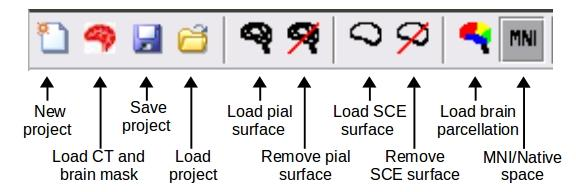

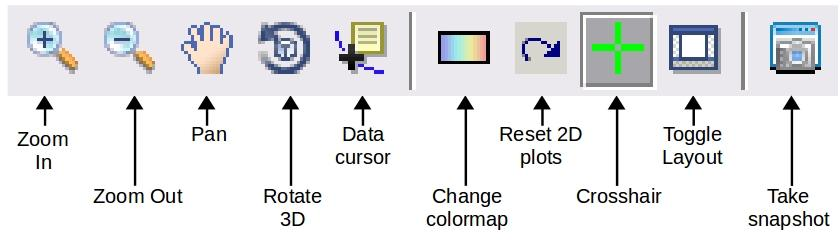

### Steps

- Click "New project" and load *$SUBJECTS_DIR/<PATIENT NAME>/mri/orig.nii*

- Click "Load CT and brain mask" and load *$SUBJECTS_DIR/<PATIENT NAME>/ct/postop_ct_coreg_<method>.nii*. For the brain mask I recommed loading the co-registered CT again. Using other masks like ribbon.nii might make it hard to visualize other landmarks like bolts, which are sometimes useful when navigating electrode locations

- Follow [this tutorial](https://sourceforge.net/p/ielectrodes/wiki/Localization%20and%20labeling%20of%20intracranial%20electrodes/) to threshold CT, select above-threshold voxels, cluster and label electrodes.

- You can always save your progress at any stage. The file

- You can save electrode outputs in various forms. For generating the label tables in later steps, select the second output option. It generates a plain txt file with channel name and XYZ coordinates in the native T1 space. It is recommended that you save it as *$SUBJECTS_DIR/<PATIENT NAME>/iel/<PATIENT NAME>_elec.txt* 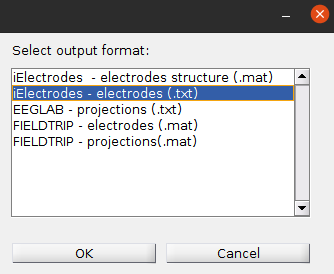

## [If using Behke-Fried depth electrodes] Estimate microwire location

iElectrodes cannot properly recognize microwires (which may or may not be visible on a post-op CT). A workaround is to estimate their location using locations of the 1st and 2nd electrodes (deepest two) and the distance between the first electrode and the microwire bundle.

### Input

- Electrode location .txt file (select from GUI)

- Known distance from the microwire bundle to the deepest macro contact (specify in code below)

### Output

- New electrode location .txt file with suffix "_u"

% Specify distance from the microwire bundle to the deepest macro contact
% (in mm)
micro_to_macro_dist = 3.75;

% Select the electrode output .txt file
estimate_micro(pat, micro_to_macro_dist)

## Get FreeSurfer labels in the native space

Since recon-all also produces brain segmentation and parcellation, we can automatically read the label value for each electrode from <aparc.***.mgz> files and find the corresponding label from *$FREESURFER_HOME/FreeSurferColorLUT.txt*. For details of the parcellations see [https://surfer.nmr.mgh.harvard.edu/fswiki/CorticalParcellation](https://surfer.nmr.mgh.harvard.edu/fswiki/CorticalParcellation)

### Input

- Electrode location .txt file (select from GUI)

### Output

- Electrode location table (in native space) at *$SUBJECTS_DIR/<PATIENT NAME>/iel/<PATIENT NAME>_elec_native.csv*

label_native(config, pat)

## Get electrode coordinates in MNI305 and MNI152 space

For group-level visualization of electrode location, mapping locations from native to standardized spaces is usually helpful. This section does two linear transforms to electrode locations to map them to:

- MNI305, also known as the fsaverage space. FreeSurfer automatically co-registers the native T1 onto this space and stores the native-to-MNI305 transformation matrix at *$SUBJECTS_DIR/<PATIENT NAME>/mri/transforms/talairach.xfm.*

- MNI152 space. The MNI305-to-MNI152 matrix is provided in [https://surfer.nmr.mgh.harvard.edu/fswiki/CoordinateSystems](https://surfer.nmr.mgh.harvard.edu/fswiki/CoordinateSystems).

In addition to generating location tables just like in the previous section, the code also automatically generates .node files. These are useful for visualizing electrode locations in some other softwares (e.g., BrainNet Viewer, Surf Ice). Below is an example visualization of *_elec_mni305.node on top of rh.curv in Surf Ice:

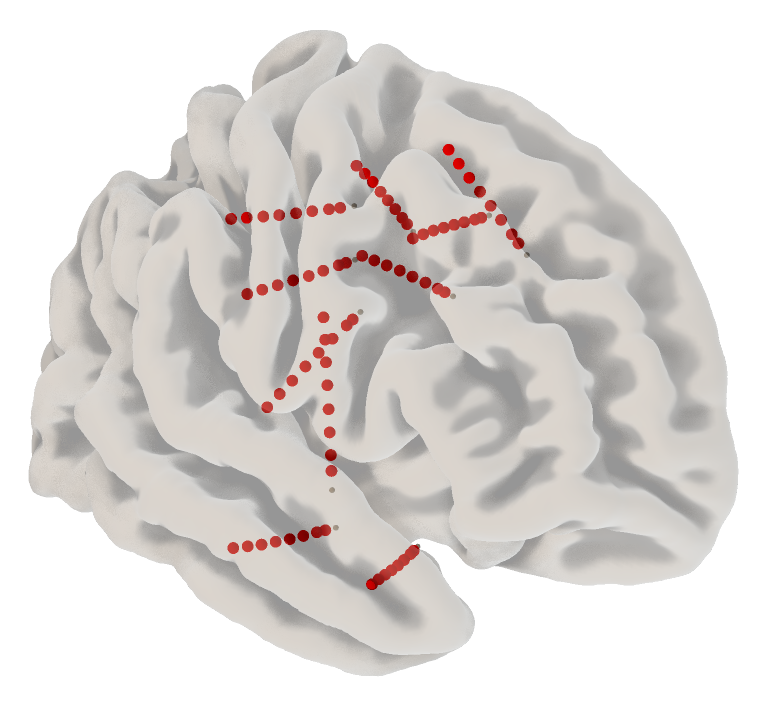

### Input

- Electrode location .txt file (select from GUI)

### Output

- Electrode location table (in MNI305/fsaverage) at *$SUBJECTS_DIR/<PATIENT NAME>/iel/<PATIENT NAME>_elec_mni305.csv*

- Electrode location node file (in MNI305/fsaverage) at *$SUBJECTS_DIR/<PATIENT NAME>/iel/<PATIENT NAME>_elec_mni305.node*

- Electrode location table (in MNI152) at *$SUBJECTS_DIR/<PATIENT NAME>/iel/<PATIENT NAME>_elec_mni152.csv*

- Electrode location node file (in MNI152) at *$SUBJECTS_DIR/<PATIENT NAME>/iel/<PATIENT NAME>_elec_mni152.node*

label_mni(pat)